% Generate a square waveform
Fs = 1000; % Sampling frequency in Hz
T = 1/Fs; % Sampling period
t = 0:T:1-T; % Time vector

f = 5; % Frequency of square wave
x = square(2*pi*f*t); % Square waveform

% Compute FFT
X = fft(x);
n = length(x);
frequencies = (0:n-1)*(Fs/n); % Frequency vector

% Magnitude and phase
magnitude = abs(X)/n

magnitude =          0         0         0         0         0    0.6366         0         0         0         0         0         0         0         0         0    0.2123         0         0         0         0         0         0         0         0         0    0.1275         0         0         0         0         0         0         0         0         0    0.0911         0         0         0         0         0         0         0         0         0    0.0710         0         0         0         0


phase = angle(X)

phase =          0         0         0         0         0   -1.5551         0         0         0         0         0         0         0         0         0   -1.5237         0         0         0         0         0         0         0         0         0   -1.4923         0         0         0         0         0         0         0         0         0   -1.4608         0         0         0         0         0         0         0         0         0   -1.4294         0         0         0         0


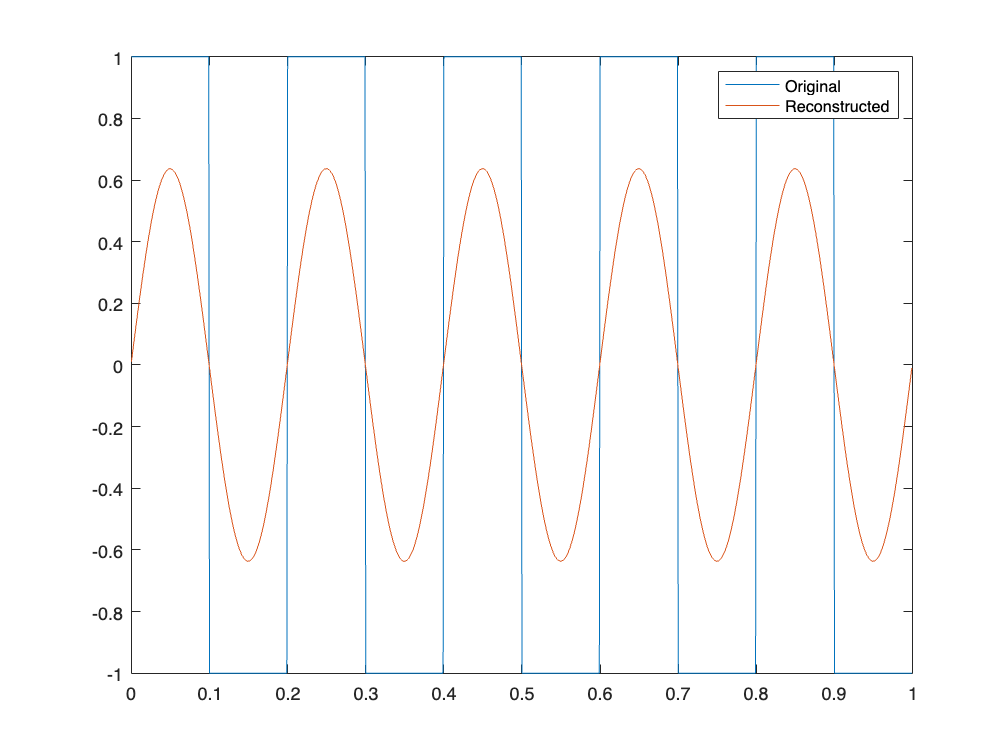

N = 10; % Number of terms
reconstructed = zeros(size(t));

for k = 1:N
    coefficient = magnitude(k);
    angFreq = 2*pi*frequencies(k);
    reconstructed = reconstructed + coefficient*cos(angFreq*t + phase(k));
end

% Plot original and reconstructed signals
plot(t, x, t, reconstructed);
legend('Original', 'Reconstructed');